% Einlesen des Testspektrums ueber Position im Hypercube
test_data = hcube.DataCube(1420,524, :);  % aus Glimpse (y Bildkoordinate, x Bildkoordinate,)
data =  reshape(test_data, [], size(test_data, 3));

% Zentrale Wellenlaengen der Filter (gleich wie in Intgralmodell HSI!)
filter_wl = [1150, 1200,1250, 1400];
% Bereiche der Filter initiieren
filter_regions = zeros(length(filter_wl), 2);

% Halbwertsbreite Filter
fwhm = 10;
hbf = fwhm/2;
for i = 1:length(filter_wl)
    filter_regions(i,1) = filter_wl(i)-hbf;
    filter_regions(i,2) = filter_wl(i)+hbf;
end

integral_values = zeros(1, length(filter_regions));
 
% Funktion erstellen durch Interpolation
interp_function = @(x) interp1(wavelengths, data, x, 'linear', 'extrap');
% Berechnung des Integrals fuer jeden Bereich
for j = 1:length(filter_regions)
    fun = interp_function;
    integral_values(:,j) = integral(fun, filter_regions(j,1), filter_regions(j,2));
end

% Normierung und Transformation des unbekannten Spektrums
centeredUnknownSpectrum = zscore(integral_values);
projectedUnknownSpectrum = centeredUnknownSpectrum * coeff(:, 1:3);

% Identifikation ueber kNN-Algorithmus
mdl = fitcknn(X_pca, y, 'NumNeighbors', 3);
predictedLabel = predict(mdl, projectedUnknownSpectrum)

predictedLabel = 3

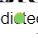


% Plotten der Ergebnisse
figure;
map = [ 0.2235294117647059  0.3137254901960784         0.38823529411764707
            0.07058823529411765  0.596078431372549  0.6784313725490196
            0.8941176470588236  0.7607843137254902  0.23921568627450981
            0.8196078431372549  0.30196078431372547  0.5137254901960784
            0.49019607843137253  0.8156862745098039  0.3803921568627451
];

colormap (map);
scatter3(X_pca(:, 1), X_pca(:, 2), X_pca(:, 3), 40, y, 'filled');
hold on;

% Plotten des unbekannten Spektrums im Hauptkomponentenraum
scatter3(projectedUnknownSpectrum(1), projectedUnknownSpectrum(2), projectedUnknownSpectrum(3), 100, predictedLabel, 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 2);

% Textlabels der einzelnen Materialien
classLabels = {'HDPE', 'LDPE', 'PET', 'PP', 'PS'};
for label = 1:5
    idx = (y == label);
    text(mean(X_pca(idx, 1)), mean(X_pca(idx, 2)), mean(X_pca(idx, 3)), classLabels{label}, ...
        'HorizontalAlignment', 'center', 'BackgroundColor', [1 1 1], 'EdgeColor', [1 1 1]);
end

% Textlabel mit dem vorhergesagten Material
text(projectedUnknownSpectrum(1), projectedUnknownSpectrum(2) + 1.5, projectedUnknownSpectrum(3), ['Predicted: ', num2str(predictedLabel)], ...
    'HorizontalAlignment', 'center', 'BackgroundColor', [1 1 1], 'EdgeColor', [1 1 1]);

% Diagrammanpassungen
view(48, 134);
set(gca, 'FontSize', 18);
title('PCA zur Kunststoffidentifikation');
xlabel('Principal Component 1');
ylabel('Principal Component 2');
zlabel('Principal Component 3');